# 7.3 窗函数法的设计思想：理想低通的 hd(n) 无限长 → 截断 → 吉布斯现象、过渡带 4π/N、阻带 −21 dB（教材例 7.5—7.7）

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if isempty(here), here = pwd; end
outdir = fullfile(here, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：理想低通（带线性相位 α=(N−1)/2）的 hd(n)=sin[ωc(n−α)]/[π(n−α)] 无限长，矩形窗截成 N 点（教材式 (7.2.4)(7.2.5)）

wc = 0.5*pi; N = 51; alpha = (N - 1)/2;
nn = -30:80; hdLong = ideal_lp(wc, alpha, nn);                      % 两头都不为零
n = 0:N-1; h51 = ideal_lp(wc, alpha, n);                            % 截断：h(n)=hd(n)R_N(n)

## 演示2：吉布斯现象——不管 N 多大，通带最大过冲都约 8.95%，ωc 处恒为 0.5（教材 7.2.2）

w = linspace(0, pi, 8192); Ns = [21 51 101]; ov = zeros(1, 3); atWc = zeros(1, 3); Hs = cell(1, 3);
for i = 1:3
    Ni = Ns(i); hi = ideal_lp(wc, (Ni - 1)/2, 0:Ni-1); Hi = abs(polyval(fliplr(hi), exp(-1i*w)));
    Hs{i} = Hi; ov(i) = max(Hi(w < wc)) - 1; atWc(i) = interp1(w, Hi, wc);
end

## 演示3：矩形窗的频谱 W_R(ω)=sin(Nω/2)/sin(ω/2)：主瓣宽 4π/N，第一旁瓣 −13 dB（教材式 (7.2.7)、图 7.2.2）

WR = sin(N*w/2)./sin(w/2); WR(1) = N;
mainlobe = 2*pi/N;                                                  % 第一个零点
[pks, locs] = local_maxima(abs(WR)); sidelobe_dB = 20*log10(pks(1)/N);   % 第一旁瓣相对主瓣（ω=0 的主瓣在端点，不在局部极大里）

## 演示4：N=51 矩形窗低通的 dB 响应：阻带最大旁瓣 −21 dB；过渡带（通带最后一个峰到阻带第一个谷）≈ 4π/N（教材 7.2.2 三条结论）

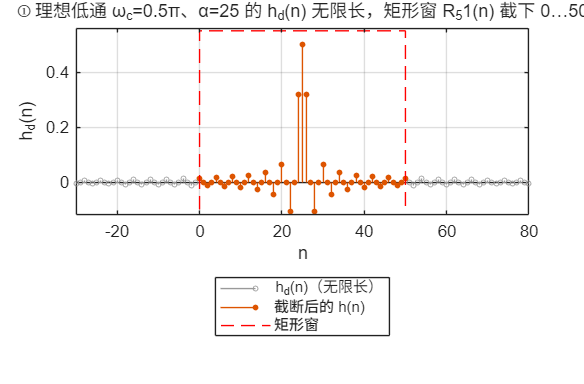

H51 = Hs{2}; dB51 = 20*log10(H51);
[pk, lc] = local_maxima(H51); iPass = lc(lc < find(w >= wc, 1)); wPassPeak = w(iPass(end));           % 通带最后一个峰
[~, lmin] = local_maxima(-H51); iStop = lmin(lmin > find(w >= wc, 1)); wStopMin = w(iStop(1));          % 阻带第一个谷
transWidth = wStopMin - wPassPeak;
stopAtt = -20*log10(max(H51(w > wStopMin)));                         % 阻带最小衰减（第一旁瓣峰）

if ~LIVE, f1 = figure('Name','03 窗函数法思想','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); stem(nn, hdLong, 'MarkerSize', 3, 'Color', [0.6 0.6 0.6]); hold on; stem(n, h51, 'filled', 'MarkerSize', 3);
plot([0 0 N-1 N-1], [-0.1 0.55 0.55 -0.1], 'r--'); grid on; xlim([-30 80]); ylim([-0.12 0.56]); xlabel('n'); ylabel('h_d(n)');
title(sprintf('① 理想低通 ω_c=0.5π、α=%d 的 h_d(n) 无限长，矩形窗 R_%d(n) 截下 0…%d', alpha, N, N-1));
legend('h_d(n)（无限长）', '截断后的 h(n)', '矩形窗');

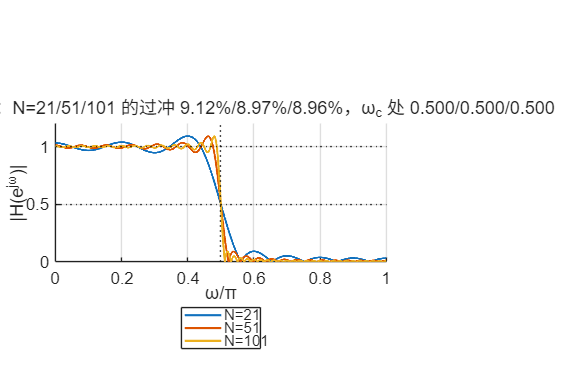

newpanel(); hold on; for i = 1:3, plot(w/pi, Hs{i}, 'LineWidth', 1.3); end
yline(1, 'k:'); yline(0.5, 'k:'); xline(wc/pi, 'k:'); grid on; xlabel('ω/π'); ylabel('|H(e^{jω})|');
title(sprintf('② 吉布斯现象：N=21/51/101 的过冲 %.2f%%/%.2f%%/%.2f%%，ω_c 处 %.3f/%.3f/%.3f', 100*ov, atWc));
legend(compose('N=%d', Ns));

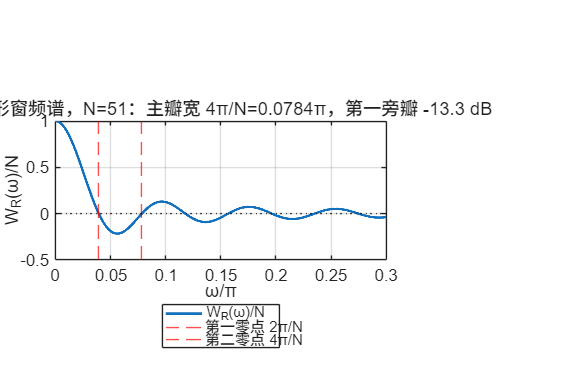

newpanel(); plot(w/pi, WR/N, 'LineWidth', 1.6); hold on; xline(mainlobe/pi, 'r--'); xline(2*mainlobe/pi, 'r--');
yline(0, 'k:'); grid on; xlim([0 0.3]); xlabel('ω/π'); ylabel('W_R(ω)/N');
title(sprintf('③ 矩形窗频谱，N=%d：主瓣宽 4π/N=%.4fπ，第一旁瓣 %.1f dB', N, 2*mainlobe/pi, sidelobe_dB));
legend('W_R(ω)/N', '第一零点 2π/N', '第二零点 4π/N');

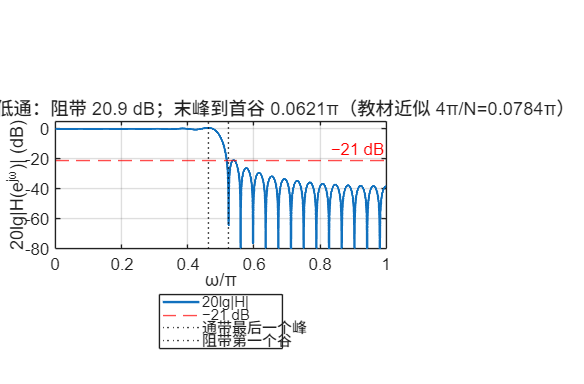

newpanel(); plot(w/pi, dB51, 'LineWidth', 1.4); hold on; yline(-21, 'r--', '−21 dB'); xline(wPassPeak/pi, 'k:'); xline(wStopMin/pi, 'k:');
grid on; ylim([-80 5]); xlabel('ω/π'); ylabel('20lg|H(e^{jω})| (dB)');
title(sprintf('④ N=%d 矩形窗低通：阻带 %.1f dB；末峰到首谷 %.4fπ（教材近似 4π/N=%.4fπ）', N, stopAtt, transWidth/pi, 4/N));
legend('20lg|H|', '−21 dB', '通带最后一个峰', '阻带第一个谷');

if ~LIVE, sgtitle('窗函数法：截断 = 频域卷积矩形窗的频谱；过冲 8.95% 不随 N 减小，过渡带 4π/N 随 N 变窄'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '03-window-method.png'), 'Resolution', 150); end

## 教师核验

assert(all(abs(ov - 0.0895) < 0.004), '吉布斯过冲应约 8.95%');
assert(all(abs(atWc - 0.5) < 0.01), 'ω_c 处应约 0.5');
assert(abs(sidelobe_dB + 13.3) < 0.5, '矩形窗第一旁瓣应约 −13 dB');
assert(abs(stopAtt - 21) < 1, '矩形窗低通阻带应约 −21 dB');
assert(abs(transWidth - 4*pi/N) < pi/N, '过渡带应约 4π/N');   % 实测约 3.2π/N：峰谷在 ω_c±1.6π/N，教材用主瓣宽 4π/N 作近似
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'wc_over_pi', wc/pi, 'N_list', Ns, 'gibbs_overshoot', ov, 'H_at_wc', atWc, 'rect_first_sidelobe_dB', sidelobe_dB, 'mainlobe_width_over_pi', 2*mainlobe/pi, ...
    'N51_stopband_att_dB', stopAtt, 'N51_transition_over_pi', transWidth/pi, 'four_pi_over_N', 4/N, 'h51_center5', h51(alpha-1:alpha+3), 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-window-method.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

            matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                    run_at: '2026-09-18 22:16:27'
                wc_over_pi: 0.5000
                    N_list: [21 51 101]
           gibbs_overshoot: [0.0912 0.0897 0.0896]
                   H_at_wc: [0.5000 0.5000 0.5000]
    rect_first_sidelobe_dB: -13.2503
    mainlobe_width_over_pi: 0.0784
       N51_stopband_att_dB: 20.9407
    N51_transition_over_pi: 0.0621
            four_pi_over_N: 0.0784
               h51_center5: [1.9491e-17 0.3183 0.5000 0.3183 1.9491e-17]
         all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_mcnta\results


## 本地函数

function h = ideal_lp(wc, alpha, n)
% 带延迟 α 的理想低通单位脉冲响应：sin[ωc(n−α)]/[π(n−α)]，n=α 处为 ωc/π
h = zeros(size(n)); i = abs(n - alpha) > 1e-12;
h(i) = sin(wc*(n(i) - alpha))./(pi*(n(i) - alpha)); h(~i) = wc/pi;
end

function [pk, loc] = local_maxima(x)
loc = find(x(2:end-1) > x(1:end-2) & x(2:end-1) >= x(3:end)) + 1; pk = x(loc);
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end